clc; clear; close all;

## Get Input Samples from RTL-SDR

%% RTL-SDR Paramters
centerFreq   = 96.7e6;      % 중심 주파수 [Hz]
sampleRate   = 1.92e6;      % 샘플레이트 [Hz]
numSamples   = 2048;        % 프레임당 샘플 수
numFrames    = 10000;       % 수집할 프레임 수

%% RTL-SDR Configuration
rxsdr = comm.SDRRTLReceiver('0','CenterFrequency',centerFreq,'SampleRate',sampleRate, ...
    'SamplesPerFrame',numSamples,'EnableTunerAGC',true,'OutputDataType','single')

rxsdr =   comm.SDRRTLReceiver with properties:

           RadioAddress: '0'
        CenterFrequency: 96700000
         EnableTunerAGC: true
             SampleRate: 1920000
         OutputDataType: 'single'
        SamplesPerFrame: 2048
    FrequencyCorrection: 0
        EnableBurstMode: false



radioInfo = info(rxsdr)

radioInfo =     The following values show radio settings, not the property 
    values of RTL-SDR receiver System object. For more information, 
    type 'help comm.SDRRTLReceiver'.

                RadioName: 'Generic RTL2832U OEM'
             RadioAddress: '0'
                TunerName: 'R820T'
             Manufacturer: 'Realtek'
                  Product: 'RTL2838UHIDIR'
               GainValues: [0 0.9000 1.4000 2.7000 3.7000 7.7000 8.7000 12.5000 14.4000 15.7000 16.6000 19.7000 20.7000 22.9000 25.4000 28 29.7000 32.8000 33.8000 36.4000 37.2000 38.6000 40.2000 42.1000 43.4000 43.9000 44.5000 48 49.6000]
      RTLCrystalFrequency: 28800000
    TunerCrystalFrequency: 28800000
             SamplingMode: 'Quadrature'
             OffsetTuning: 'Disabled'
          CenterFrequency: 96700000
               SampleRate: 1920000
      FrequencyCorrection: 0



%% Buffer for Baseband IQ samples
iqData = complex(zeros(numSamples, numFrames));

%% Receiving Baseband IQ samples from RTL-SDR
fprintf('수집 시작: %d 프레임 × %d 샘플\n', numFrames, numSamples);

수집 시작: 10000 프레임 × 2048 샘플



for k = 1:numFrames
    [samples, ~] = rxsdr();  
    iqData(:, k) = samples;    
end

fprintf('수집 완료. 총 %d 샘플\n', numel(iqData));

수집 완료. 총 20480000 샘플



%% Flattening matrix to vector
iqData = iqData(:);

%% Remove RTL-SDR
release(rxsdr);

## Parameter for FM Radio

%% Parameter for FM signal processing
fs_rf = 1.92e6;         % sampling rate for baseband IQ samples
fs_audio = 48000;       % sampling rate for audio signal
freq_dev = 75e3;        % frequency deviation
tau = 75e-6;
tau2 = tau / 10; 

%% Parameter for FIR Decimator
% Channel LPF + 5:1 Decimation (1.92M → 384k)
decim1 = 5;
f1 = [0 (154e3/(fs_rf/2)) (230e3/(fs_rf/2)) 1];
A1 = [1 1 0 0];
CoefFilter1 = firpm(48,f1,A1);
fs_if1 = fs_rf / decim1;  % 384 kHz

% Anti-Aliasing LPF + 2:1 Decimation (384k → 192k)
decim2 = 2;
f2 = [0 (72e3/(fs_if1/2)) (120e3/(fs_if1/2)) 1];
A2 = [1 1 0 0];
CoefFilter2 = firpm(15,f2,A2);
fs_if2 = fs_if1 / decim2; % 192 kHz

% Anti-Aliasing LPF + 2:1 Decimation (192k → 96k)
decim3 = 2;
f3 = [0 (24e3/(fs_if2/2)) (72e3/(fs_if2/2)) 1];
A3 = [1 1 0 0];
CoefFilter3 = firpm(11,f3,A3);
fs_if3 = fs_if2 / decim3; % 96 kHz

% Anti-Aliasing LPF + 2:1 Decimation (96k → 48k)
decim4 = 2;
f4 = [0 (20e3/(fs_if3/2)) (28e3/(fs_if3/2)) 1];
A4 = [1 1 0 0];
CoefFilter4 = firpm(35,f4,A4);
fs_if4 = fs_if3 / decim4; % 48 kHz

%%  If you want to check frequency response for filter, then use this command.
% filterAnalyzer(CoefFilter1,FilterNames=["Filter1"], MagnitudeMode="db")

%% De-emphasis IIR Filter: H(s) = (tau2*s + 1) / (tau*s + 1)
[b_de, a_de] = bilinear([tau2 1], [tau 1], fs_audio);


## Golden Reference with MATLAB Script

%% Channel LPF
filtered_iq = filter(CoefFilter1, 1, iqData);
filtered_iq = filtered_iq(1:decim1:end);

%% Cross-Multiply Discriminator
dphi = angle(filtered_iq(2:end) .* conj(filtered_iq(1:end-1)));

%% Anti-Aliasing LPF
filtered_audio = filter(CoefFilter2, 1, dphi);
filtered_audio = filtered_audio(1:decim2:end);

filtered_audio = filter(CoefFilter3, 1, filtered_audio);
filtered_audio = filtered_audio(1:decim2:end);

filtered_audio = filter(CoefFilter4, 1, filtered_audio);
filtered_audio = filtered_audio(1:decim2:end);

%% De-emphasis IIR Filter
audio_out_gd = filter(b_de, a_de, filtered_audio);

## Our DUT in Simulink

%% Simulation Time for Simulink
SimTime = length(iqData);
SimTime = SimTime / fs_rf;

%% Run Simulink
slout = sim("fm_radio_simulink_v5.slx");


%% Get Log from simulation of Simulink
rx_iq_sl = getLogged(slout, 'rx_iq');
filtered_iq_sl = getLogged(slout, 'filtered_iq');
dphi_sl = getLogged(slout, 'dphi');
filtered_audio_sl = getLogged(slout, 'filtered_audio');
audio_out_sl = getLogged(slout, 'audio_out');
out_valid_sl = getLogged(slout, 'valid_out');
audio_out_sl = audio_out_sl(out_valid_sl);

## Compare the results of Golden Reference and DUT

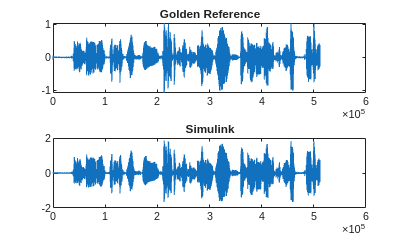

%% claming the length for compare
N = min(length(audio_out_gd), length(audio_out_sl));
audio_gd_cmp = audio_out_gd(1:N);
audio_sl_cmp = audio_out_sl(1:N);

%% Plot the results.
figure;
subplot(2,1,2); plot(audio_sl_cmp); title('Simulink');
subplot(2,1,1); plot(audio_gd_cmp); title('Golden Reference');


Maximum error for Golden Reference vs Simulink out of 511998 values
 8.403962e-01 (absolute), 7.758992e+01 (percentage)


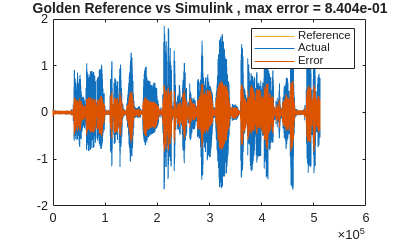


compareData(audio_gd_cmp,audio_sl_cmp,{2 1 1},'Golden Reference vs Simulink');

## Audio for DUT

% 저장/재생
audio_out_sl = double(audio_out_sl);
soundsc(audio_out_sl, fs_audio);